clc
close all
clear

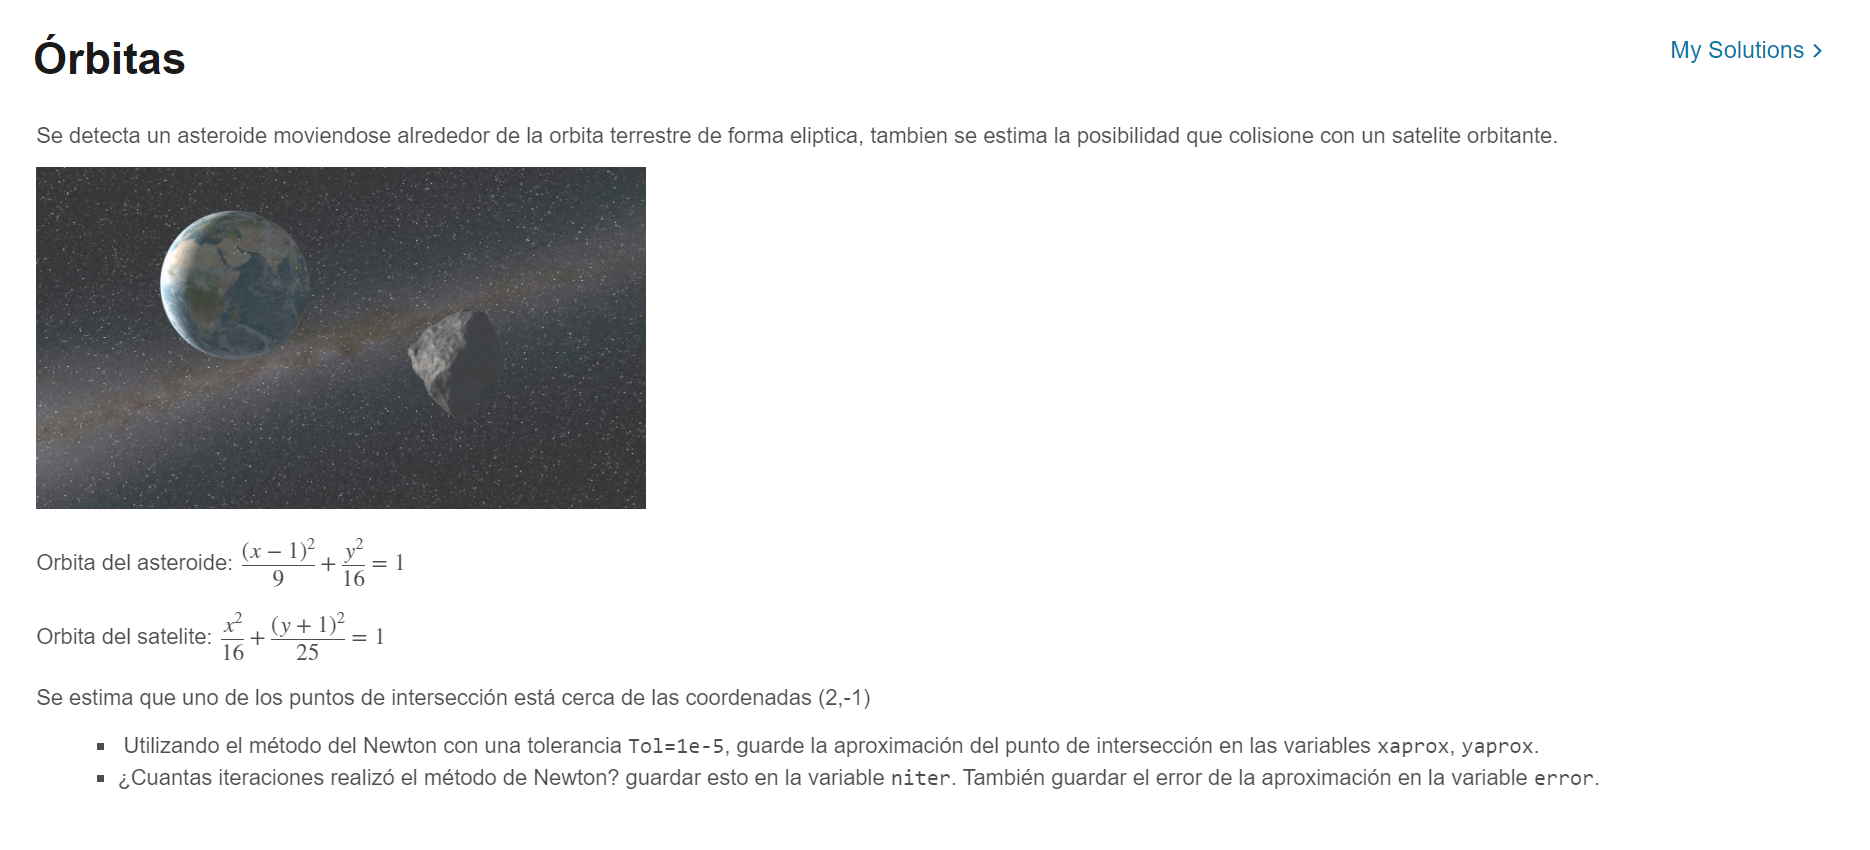

clc; clear;
syms x y
f=(x-1)^2/9+y^2/16-1

$$f = \frac{{\left(x-1\right)}^{2}}{9}+\frac{y^{2}}{16}-1$$

g=x^2/16+(y+1)^2/25-1

$$g = \frac{{\left(y+1\right)}^{2}}{25}+\frac{x^{2}}{16}-1$$

F=[f;g]

$$F = \left(\begin{array}{c} \frac{{\left(x-1\right)}^{2}}{9}+\frac{y^{2}}{16}-1\\ \frac{{\left(y+1\right)}^{2}}{25}+\frac{x^{2}}{16}-1 \end{array}\right)$$

x0=[2;-1]

x0 =      2
    -1


[r,niter,error]=newton_dos(F,x0,1e-5)

T = 7×3 table
      x          y            ea    
    ______    ________    __________

         2          -1             1
         5     -2.2778       0.54601
     4.241    -0.77669       0.34816
    3.9938    -0.50088      0.068521
    3.9784    -0.48016     0.0051706
    3.9783    -0.48007    2.2937e-05
    3.9783    -0.48007    4.8282e-10


r =     3.9783
   -0.4801


niter = 6

error = 4.8282e-10

xaprox=double(r(1))

xaprox = 3.9783

yaprox=double(r(2))

yaprox = -0.4801

### 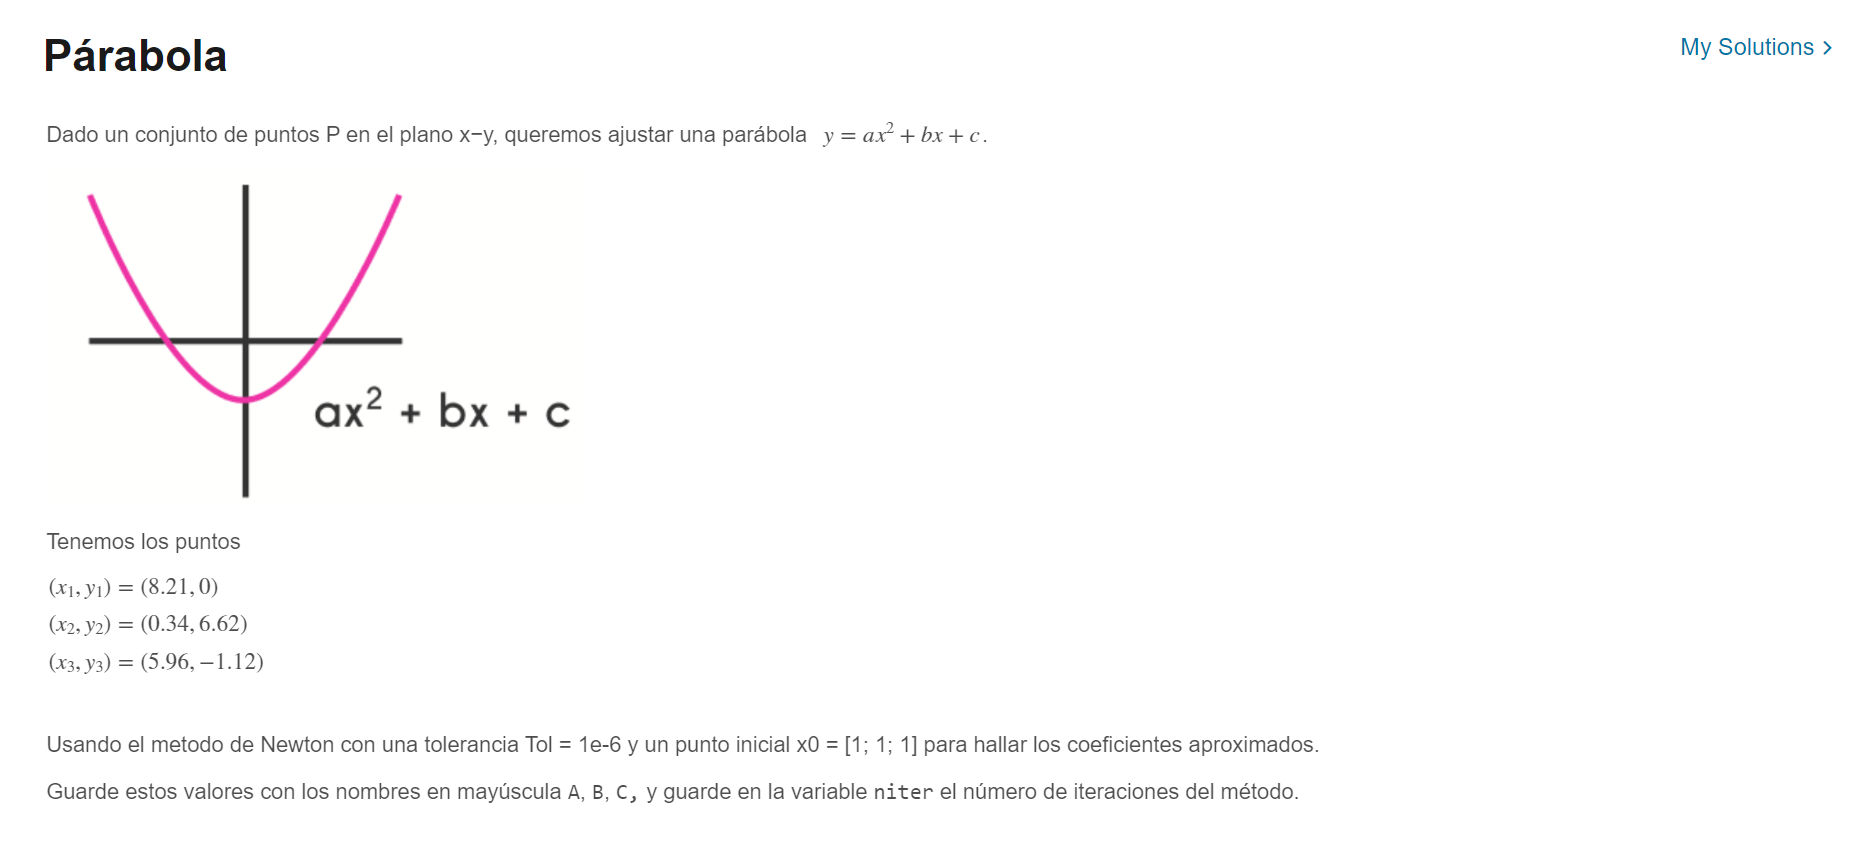

clc; clear;
syms a b c
q=a*8.21^2+b*8.21+c-0

$$q = \frac{4743141869425683\,a}{70368744177664}+\frac{821\,b}{100}+c$$

r=a*0.34^2+b*0.34+c-6.62

$$r = \frac{289\,a}{2500}+\frac{17\,b}{50}+c-\frac{331}{50}$$

t=a*5.96^2+b*5.96+c+1.12

$$t = \frac{22201\,a}{625}+\frac{149\,b}{25}+c+\frac{28}{25}$$

F=[q;r;t]

$$F = \left(\begin{array}{c} \frac{4743141869425683\,a}{70368744177664}+\frac{821\,b}{100}+c\\ \frac{289\,a}{2500}+\frac{17\,b}{50}+c-\frac{331}{50}\\ \frac{22201\,a}{625}+\frac{149\,b}{25}+c+\frac{28}{25} \end{array}\right)$$

x0=[1;1;1];
[coef,niter]=newton_tres(F,x0,1e-6)

T = 3×4 table
       a          b         c          ea    
    _______    _______    _____    __________

          1          1        1             1
    0.23825    -2.8782    7.571       0.81092
    0.23825    -2.8782    7.571    1.0961e-16


coef =     0.2382
   -2.8782
    7.5710


niter = 2

A=coef(1)

A = 0.2382

B=coef(2)

B = -2.8782

C=coef(3)

C = 7.5710

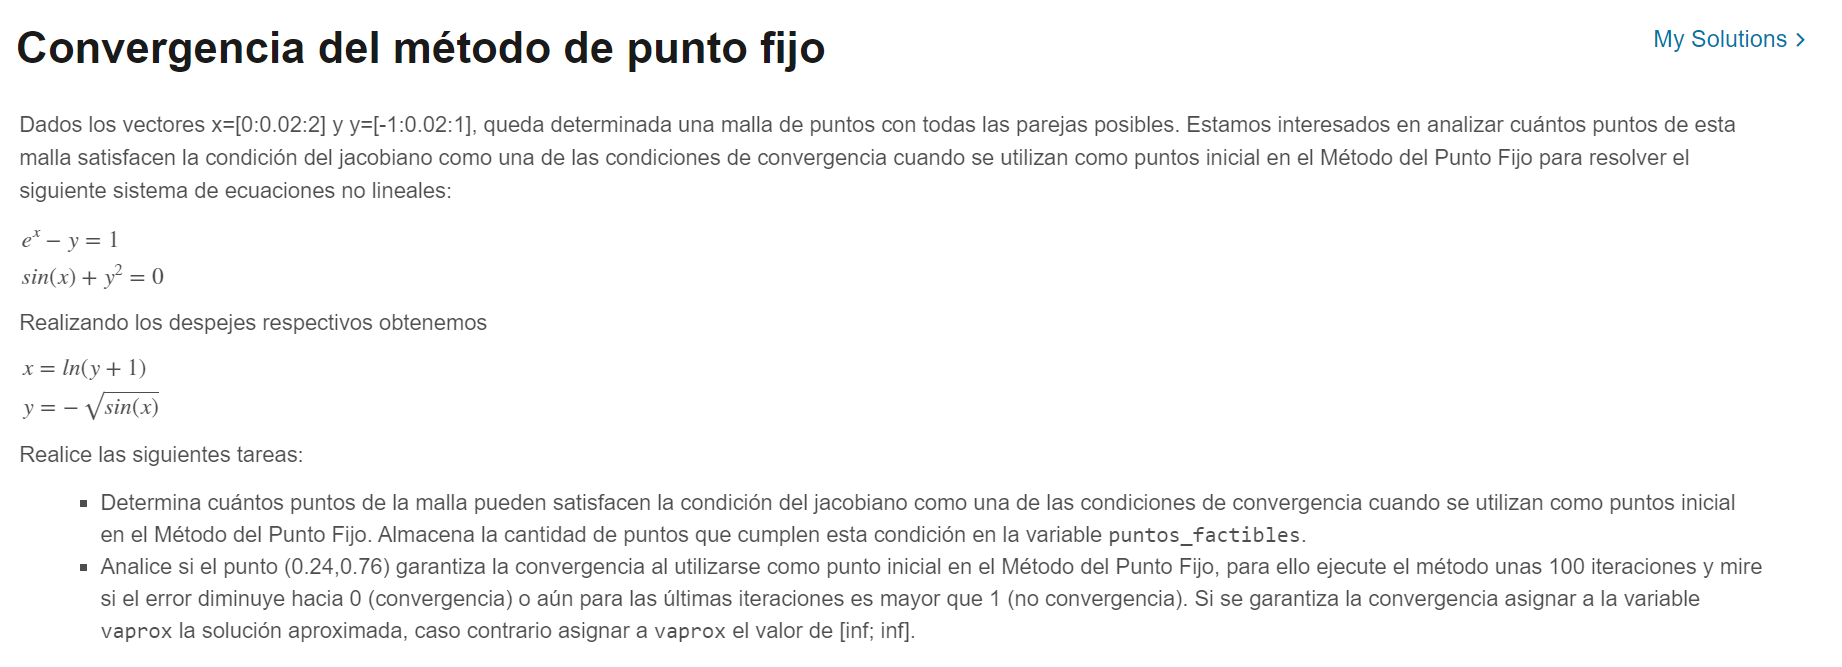

clc; clear;
x=[0:0.02:2];
y=[-1:0.02:1];

x0=[x;y]'

x0 =          0   -1.0000
    0.0200   -0.9800
    0.0400   -0.9600
    0.0600   -0.9400
    0.0800   -0.9200
    0.1000   -0.9000
    0.1200   -0.8800
    0.1400   -0.8600
    0.1600   -0.8400
    0.1800   -0.8200


syms x y
q=log(y+1)

$$q = \log\left(y+1\right)$$

r=-sqrt(sin(x))

$$r = -\sqrt{\sin\left(x\right)}$$

g=[q;r]

$$g = \left(\begin{array}{c} \log\left(y+1\right)\\ -\sqrt{\sin\left(x\right)} \end{array}\right)$$

syms x y
g=matlabFunction(g);
dg=jacobian(g(x,y),[x,y])

$$dg = \left(\begin{array}{cc} 0 & \frac{1}{y+1}\\ -\frac{\cos\left(x\right)}{2\,\sqrt{\sin\left(x\right)}} & 0 \end{array}\right)$$

dg=matlabFunction(dg);

puntos_factibles=0;
for i=1:length(x0)
    x=x0(i,1);
    for j=1:length(x0)
        y=x0(j,2);
        c=convergencia_dos(dg,x,y);
        puntos_factibles=puntos_factibles+c;
    end
end
puntos_factibles

puntos_factibles = 4450

x0=[0.24;0.76]

x0 =     0.2400
    0.7600


vaprox=pfijo_dos_iter(g,x0,100) %no converge esta porqueria

T = 101×3 table
            x                     y              ea   
    __________________    _________________    _______

      0.56531+0i          -0.48755+0i           1.6712
     -0.66855+0i           -0.7319+0i           1.2447
      -1.3164+0i                 0+0.7873i     0.70081
      0.24117+0.66695i           0+0.98378i     1.3971
      0.33846+0.77722i    -0.72463-0.48076i     1.3455
     -0.59052-1.0506i     -0.82382-0.49113i     1.3312
     -0.65053-1.2264i     -0.48961+1.0645i     0.87587
      0.16596+1.1237i     -0.52454+1.1816i      1.4457
       0.2419+1.1882i      -0.9128-0.74314i     1.1619
     -0.29003-1.454i      -0.98411-0.73413i     1.4001
     -0.30883-1.5492i     -0.83604+1.1595i     0.89156
      0.15787+1.4303i     -0.87186+1.2279i      1.4478
      0.21075+1.4668i       -1.078-0.90257i     1.0479
    -0.098788-1.657i       -1.1271-0.89034i     1.4301
 

vaprox =    0.2069 - 1.9291i
  -1.4313 + 1.1518i


vaprox=[inf;inf]

vaprox =    Inf
   Inf


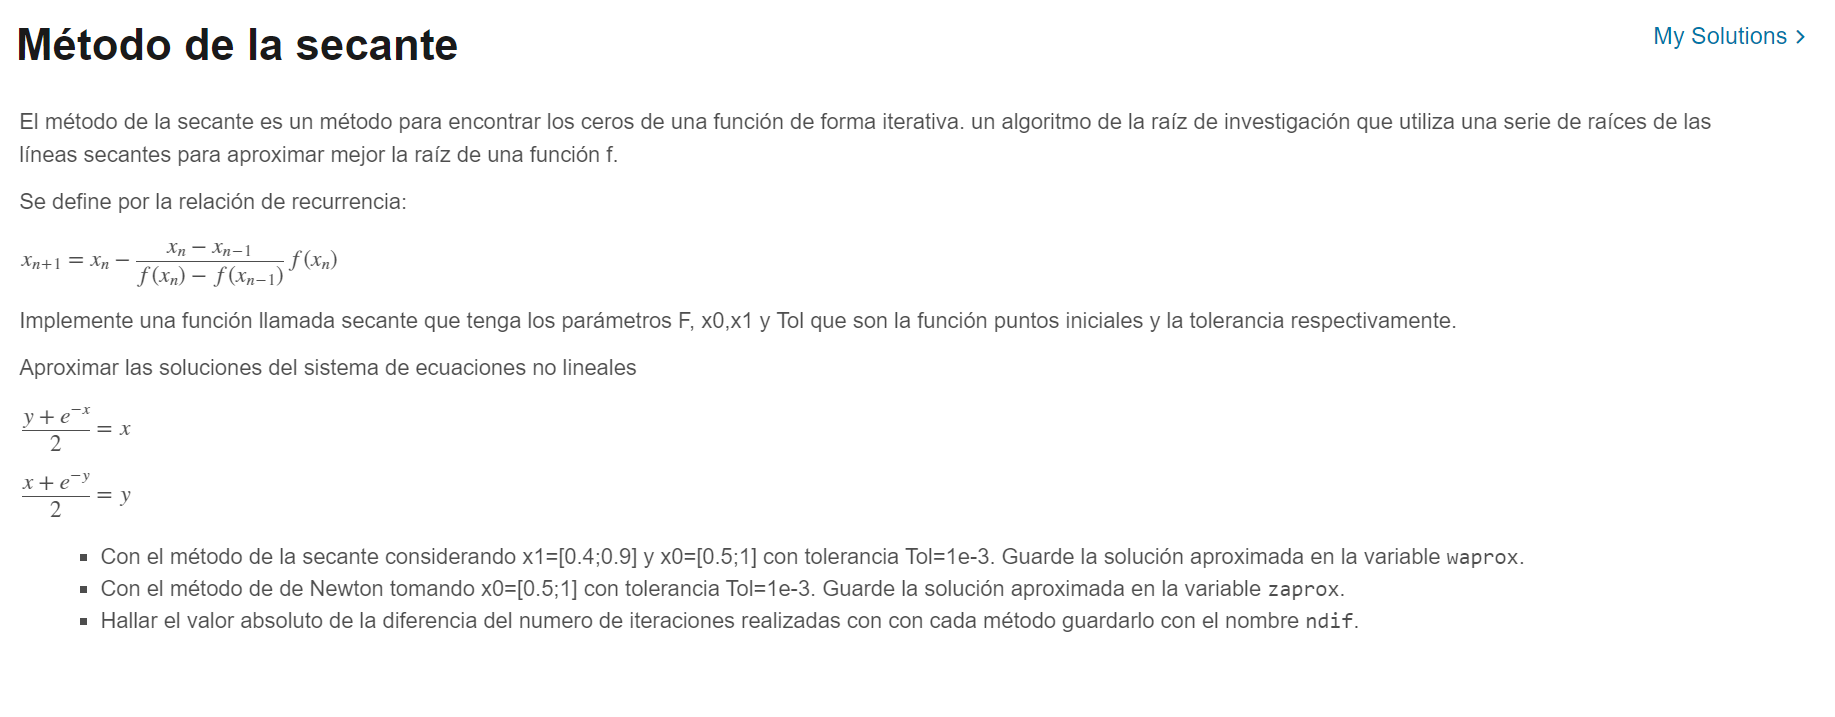

clc; clear;
syms x y
f=(y+exp(-x))/2-x

$$f = \frac{y}{2}-x+\frac{{\mathrm{e}}^{-x}}{2}$$

g=(x+exp(-y))/2-y

$$g = \frac{x}{2}-y+\frac{{\mathrm{e}}^{-y}}{2}$$

F=[f;g]

$$F = \left(\begin{array}{c} \frac{y}{2}-x+\frac{{\mathrm{e}}^{-x}}{2}\\ \frac{x}{2}-y+\frac{{\mathrm{e}}^{-y}}{2} \end{array}\right)$$

x1=[0.4;0.9]

x1 =     0.4000
    0.9000


x0=[0.5;1]

x0 =     0.5000
    1.0000


[waprox,witer]=secante(F,x0,x1,1e-3) %las primeras dos iteraciones no cuentan pq son datos previos

T = 5×3 table
       x          y           ea    
    _______    _______    __________

        0.5          1             1
        0.4        0.9             1
    0.55959    0.55066       0.44497
    0.56723    0.56774      0.021285
    0.56714    0.56714    0.00074447


waprox =     0.5671
    0.5671


witer = 3

[zaprox,ziter]=newton_dos(F,x0,1e-3)

T = 4×3 table
       x          y           ea    
    _______    _______    __________

        0.5          1             1
    0.55879    0.54671       0.57983
    0.56711    0.56708      0.025401
    0.56714    0.56714    7.2708e-05


zaprox =     0.5671
    0.5671


ziter = 3

ndif=abs(witer-ziter)   

ndif = 0

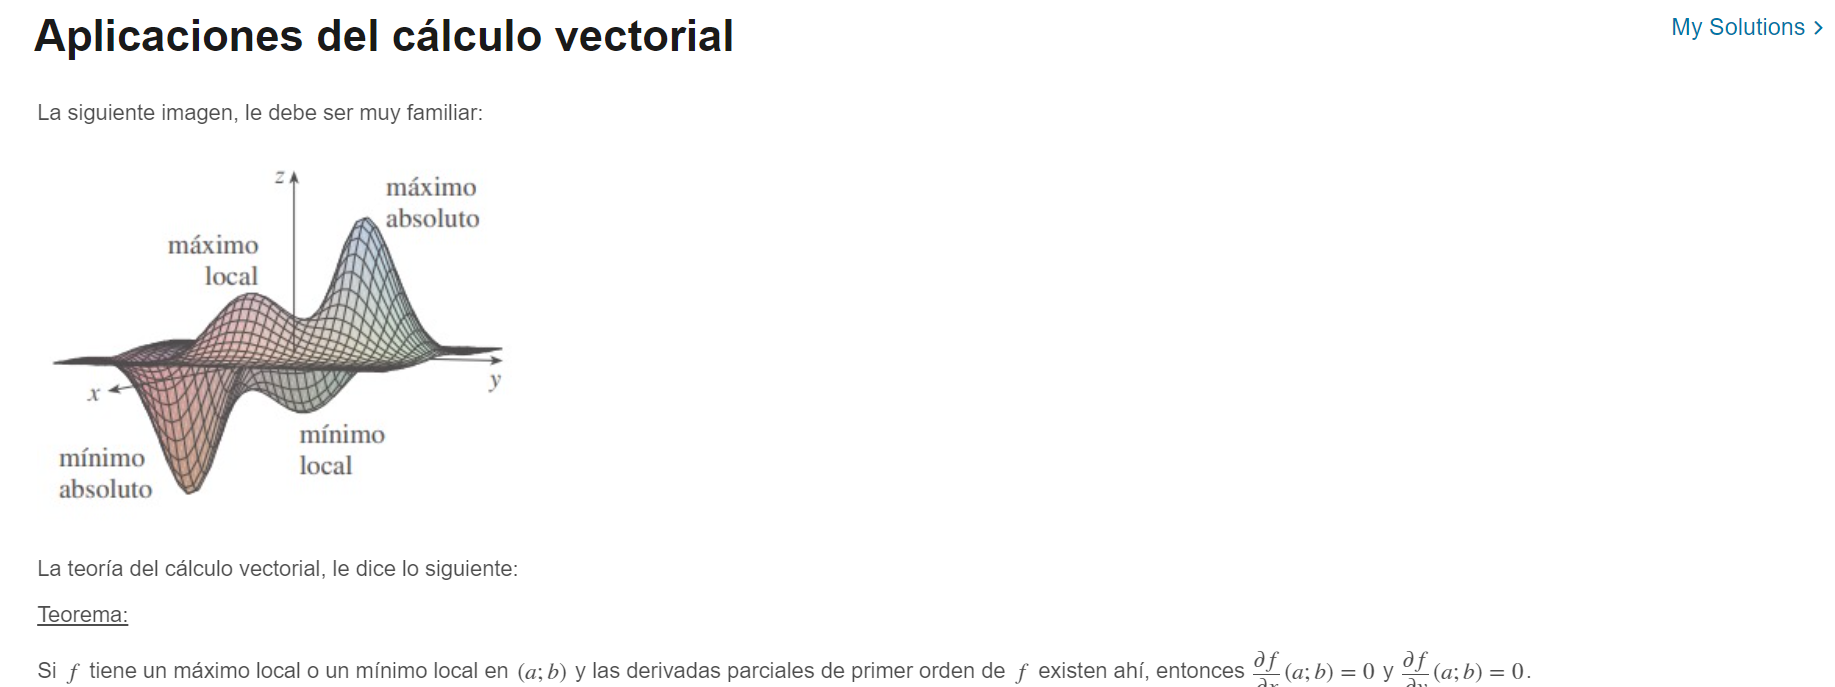

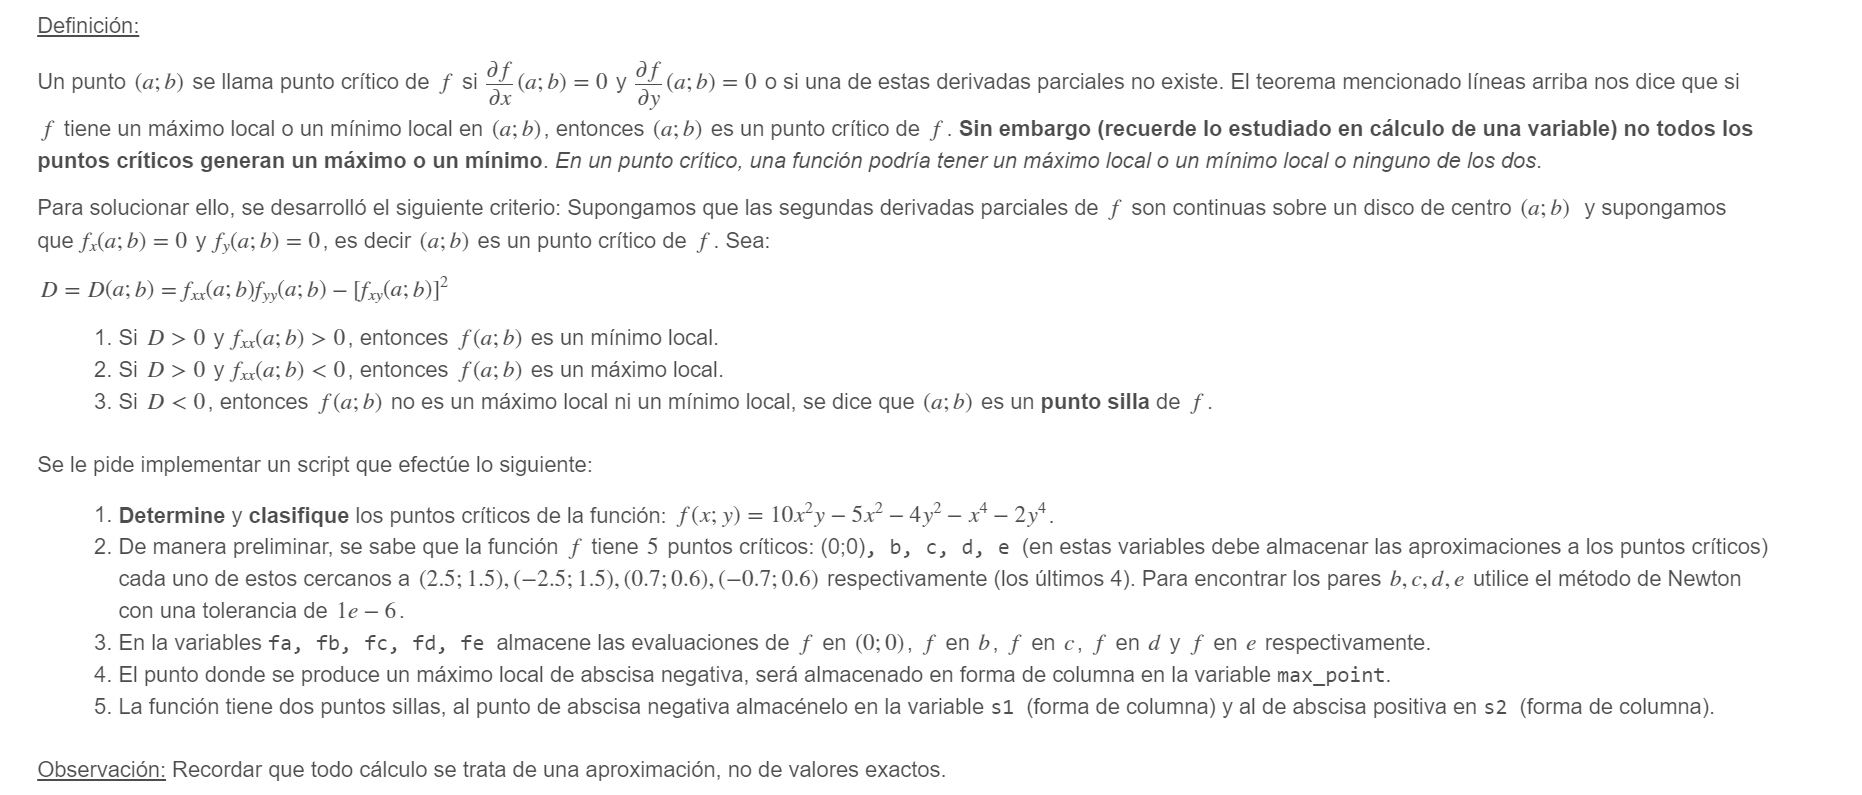

clc; clear;
syms x y
f=10*x^2*y-5*x^2-4*y^2-x^4-2*y^4

$$f = -x^{4}+10\,x^{2}\,y-5\,x^{2}-2\,y^{4}-4\,y^{2}$$

q=diff(f,x);
r=diff(f,y);
g=[q;r]

$$g = \left(\begin{array}{c} 20\,x\,y-10\,x-4\,x^{3}\\ 10\,x^{2}-8\,y^{3}-8\,y \end{array}\right)$$

tol=1e-6;
a=[0,0]'

a =      0
     0


x0=[2.5;1.5];
b=newton_dos(g,x0,tol)

T = 7×3 table
      x         y           ea    
    ______    ______    __________

       2.5       1.5             1
    2.9396    2.2335       0.19869
    2.7211    1.9717      0.077909
    2.6502    1.9035      0.021712
    2.6443    1.8984     0.0018373
    2.6442    1.8984    1.1558e-05
    2.6442    1.8984    4.3441e-10


b =     2.6442
    1.8984


x0=[-2.5;1.5];
c=newton_dos(g,x0,tol)

T = 7×3 table
       x         y           ea    
    _______    ______    __________

       -2.5       1.5             1
    -2.9396    2.2335       0.19869
    -2.7211    1.9717      0.077909
    -2.6502    1.9035      0.021712
    -2.6443    1.8984     0.0018373
    -2.6442    1.8984    1.1558e-05
    -2.6442    1.8984    4.3441e-10


c =    -2.6442
    1.8984


x0=[0.7;0.6];
d=newton_dos(g,x0,tol)

T = 5×3 table
       x          y           ea    
    _______    _______    __________

        0.7        0.6             1
    0.86986    0.64508       0.15685
     0.8566    0.64662      0.012357
    0.85666    0.64677    0.00014009
    0.85666    0.64677    1.4521e-08


d =     0.8567
    0.6468


x0=[-0.7;0.6];
e=newton_dos(g,x0,tol)

T = 5×3 table
       x           y           ea    
    ________    _______    __________

        -0.7        0.6             1
    -0.86986    0.64508       0.15685
     -0.8566    0.64662      0.012357
    -0.85666    0.64677    0.00014009
    -0.85666    0.64677    1.4521e-08


e =    -0.8567
    0.6468


f=matlabFunction(f);
fa=f(a(1),a(2))

fa = 0

fb=f(b(1),b(2))

fb = 8.4959

fc=f(c(1),c(2))

fc = 8.4959

fd=f(d(1),d(2))

fd = -1.4847

fe=f(e(1),e(2))

fe = -1.4847

X=[a b c d e]';
[max,min,silla]=dis(f,X) %de aqui vemos cual es cual 

max =          0         0
    2.6442    1.8984
   -2.6442    1.8984


min =      0     0


silla =          0         0
         0         0
         0         0
    0.8567    0.6468
   -0.8567    0.6468


max_point=c

max_point =    -2.6442
    1.8984


s1=e

s1 =    -0.8567
    0.6468


s2=d

s2 =     0.8567
    0.6468


function [z,iter,er]=newton_dos(F,x0,Tol)
syms x y 
F=matlabFunction(F);
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
i=1;
A=zeros(2,3);
A(i,1:2)=x0';
A(i,3)=error;
while error>Tol
x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
error=norm(x1-x0,"inf")/norm(x1); %usamos la norma infinito
x0=x1;
i=i+1;
A(i,1:2)=x0';
A(i,3)=error;
end
z=x0;
iter=i-1;
er=A(end,3);
T=array2table(A,'VariableNames',{'x','y','ea'})
end

function s=convergencia_dos(dg,x0,y0)
s=norm(dg(x0,y0),inf);
if s<1
    s=1;
else
    s=0;
end
end

function z=pfijo_dos_iter(g,x0,iter)
error=1;
A=zeros(2,3);
i=1;
A(i,1:2)=[g(x0(1),x0(2))]';
A(i,3)=error;
for i=0:iter
x1=g(x0(1),x0(2));
error=norm(x1-x0,inf)/norm(x1);
x0=x1;
i=i+1;
A(i,1:2)=x0';
A(i,3)=error;
end
z=x0;
T=array2table(A,'VariableNames',{'x','y','ea'})
end

function [n,iter]=secante(f,X0,X1,err)
%Calculamos la derivada de la función
g=matlabFunction(f);
ea=1;
i=1;
A=zeros(2,3);
A(i,1:2)=X0';
A(i,3)=ea;
i=2;
A(i,1:2)=X1';
A(i,3)=ea;
iter=0;
while ea>err
x0 = X0(1);
y0 = X0(2);
x1= X1(1);
y1= X1(2);
fx = (g(x1,y0)-g(x0,y0))/(x1-x0);
fy = (g(x0,y1)-g(x0,y0))/(y1-y0);
jacobianito=[fx fy];
X2 = X1 - (jacobianito)\g(x1,y1);
%Calculamos el porcentaje de error
ea=norm(X2-X1,"inf")/norm(X2);
i=i+1;
A(i,1:2)=X2';
A(i,3)=ea;
X0=X1;
X1=X2;
iter=iter+1;
end
%Mostramos los resultados en pantalla (con 3 decimales)
n=X2;
T=array2table(A,'VariableNames',{'x','y','ea'})
end



function [max,min,silla]=dis(f,X)
max=zeros(1,2);
min=zeros(1,2);
silla=zeros(1,2);
syms x y
dxx= matlabFunction( diff(diff(f,x),x) );
dyy= matlabFunction( diff(diff(f,y),y) );
dxy= matlabFunction( diff(diff(f,x),y) );

for i=1:length(X)
    
    D=dxx(X(i,1),X(i,2))*dyy(X(i,2))-(dxy(X(i,1)))^2;
    
    if (D>0) &&  ( dxx(X(i,1),X(i,2))>0 )
        min(i,1:2)=[X(i,1),X(i,2)];
        
    elseif (D>0) &&  ( dxx(X(i,1),X(i,2))<0 )
        max(i,1:2)=[X(i,1),X(i,2)];
        
    elseif (D<0)
        silla(i,1:2)=[X(i,1),X(i,2)];
        
    end
end
end

function [z,iter]=newton_tres(F,x0,Tol)
syms a b c
F = matlabFunction(F);
dF = jacobian(F(a,b,c),[a,b,c]);    
df_fun = double(dF);
error=1;
i=1;
iter=0;
A=zeros(2,4);
A(i,1:3)=x0';
A(i,4)=error;
while error>Tol
x1=x0-(df_fun)\F(x0(1),x0(2),x0(3)); %No le ponemos nada al jacobiano pq no esta en funcion de variables
error=norm(x1-x0,"inf")/norm(x1);
x0=x1;
i=i+1;
A(i,1:3)=x0';
A(i,4)=error;
iter=iter+1;
end
z=x0;
T=array2table(A,'VariableNames',{'a','b','c','ea'})
end